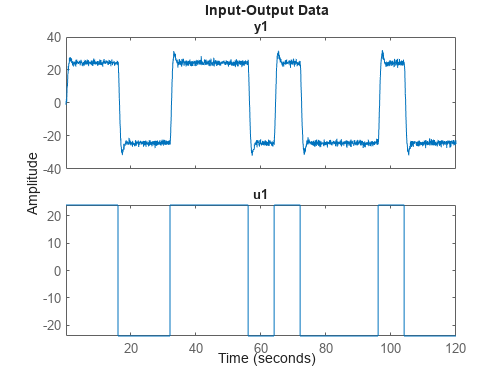

%%% HIGH SNR DATA %%%
% Simulink PRBS Inputs
samplepoint = 250;
switchconstant = 200;
amplitude = 24;
noise = 1;

% Load Data
Hangle = out.Hangle;
Hvoltage = out.Hvoltage;

% Create Identification and Validation Data Objects
HighData = iddata(Hangle, Hvoltage, Ts);
plot(HighData)

Hi_Data = HighData(1:1800);
Hv_Data = HighData(1801:2401);

% Delay Check
Hdelay = delayest(HighData)

Hdelay = 4

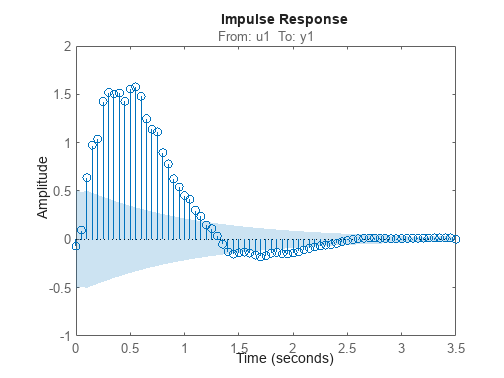

ImpRes = impulseest(HighData);
ImpRes_Plot = impulseplot(ImpRes);
showConfidence(ImpRes_Plot, 5)

% Order model Choice
% Define the range of possible model orders to test (adjust as needed)
order_range = 1:10;  % Try orders from 1 to 10 based on system complexity

% Cell array to store Hankel singular values for each model order
Hankel_SVs = cell(length(order_range), 1);

% Loop through the range of orders to estimate the state-space model and compute Hankel singular values
for i = 1:length(order_range)
    % Current model order to test
    nx = order_range(i);
    
    % Estimate the state-space model of order 'n' using n4sid
    system = n4sid(Hi_Data, nx);  % I_Data is the identification dataset
    
    % Compute the Hankel singular values for the system matrix A
    Hankel_SV = svd(system.A);  % Singular values of the system matrix A
    
    % Store the Hankel singular values in the cell array
    Hankel_SVs{i} = Hankel_SV;
end

% Display the Hankel singular values for each model order
disp('Hankel Singular Values for different model orders:');

Hankel Singular Values for different model orders:


for i = 1:length(order_range)
    fprintf('Order %d:\n', order_range(i));
    disp(Hankel_SVs{i});
end

Order 1:


    0.9265



Order 2:


    0.9272
    0.8153



Order 3:


    1.0603
    0.9009
    0.2833



Order 4:


    1.1046
    0.9994
    0.8903
    0.6355



Order 5:


    1.1723
    1.0016
    0.9996
    0.8657
    0.6803



Order 6:


    1.0847
    1.0012
    0.9983
    0.8640
    0.7628
    0.3325



Order 7:


    1.1626
    1.0002
    0.9986
    0.9909
    0.9775
    0.8512
    0.7292



Order 8:


    1.1283
    1.0004
    1.0003
    0.9999
    0.9860
    0.8892
    0.8501
    0.5076



Order 9:


    1.4013
    1.0008
    1.0006
    0.9997
    0.9994
    0.9819
    0.9577
    0.8483
    0.6742



Order 10:


    1.4741
    1.0010
    1.0006
    1.0000
    0.9968
    0.9956
    0.9855
    0.9330
    0.8465
    0.5525



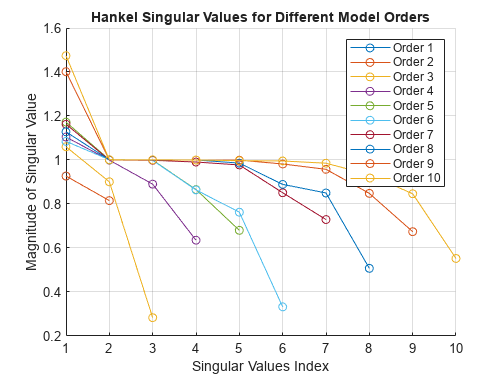

% Plot the Hankel singular values for each model order
figure;
hold on;
for i = 1:length(order_range)
    plot(Hankel_SVs{i}, 'o-', 'DisplayName', ['Order ', num2str(order_range(i))]);
end
hold off;

% Customize plot for better visualization
xlabel('Singular Values Index');
ylabel('Magnitude of Singular Value');
title('Hankel Singular Values for Different Model Orders');
legend('show');
grid on;

% transfer functions
n4sid(HighData, 1:10, "InputDelay", Hdelay); % State-space model estimation
% Create Transfer Function for Analysis
sysH = tfest(Hi_Data, 2, 1, 0);
sysH1 = tfest(Hi_Data, 2, 0, 0);
disp('Transfer Function Model:');

Transfer Function Model:


present(sysH);

                                                                                                                                                                                                                                                                                               
sysHH =                                                                                                                                                                                                                                                                                        
                                                                                                                                                                                                                                                                                               
  From input "u1" to output "y1":                                                                                                       

present(sysH1);

                                                                                                                                                                                                                                                                                                    
sysH1H1 =                                                                                                                                                                                                                                                                                           
                                                                                                                                                                                                                                                                                                    
  From input "u1" to output "y1":                                                                                        

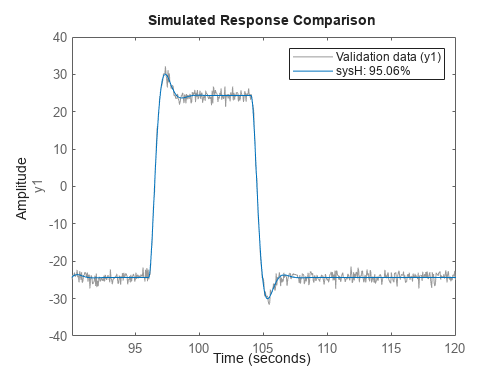

% Validate the Model
compare(Hv_Data, sysH)

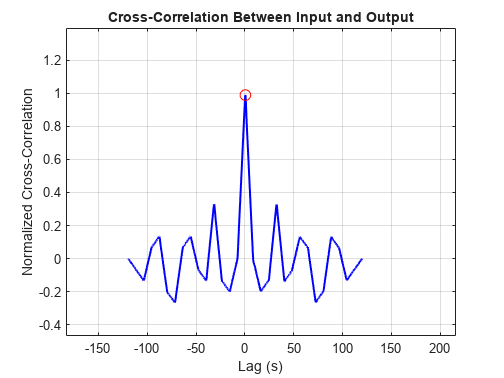

% Cross-Correlation to Check for Delay
[Hcorrelation, Hlags] = xcorr(Hangle, Hvoltage, 'normalized'); % Cross-correlation
[Hmax_corr, Hmax_idx] = max(Hcorrelation); % Find the maximum correlation

% Plot Cross-Correlation
figure;
plot(Hlags * Ts, Hcorrelation, 'b', 'LineWidth', 1.5);
hold on;
plot(Hlags(Hmax_idx) * Ts, Hmax_corr, 'ro', 'MarkerSize', 8); % Highlight max correlation point
xlabel('Lag (s)');
ylabel('Normalized Cross-Correlation');
title('Cross-Correlation Between Input and Output');
grid on;
hold off;

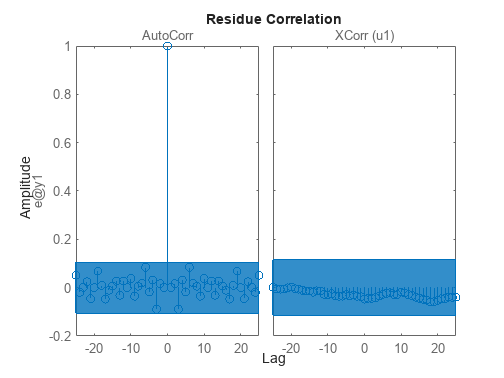

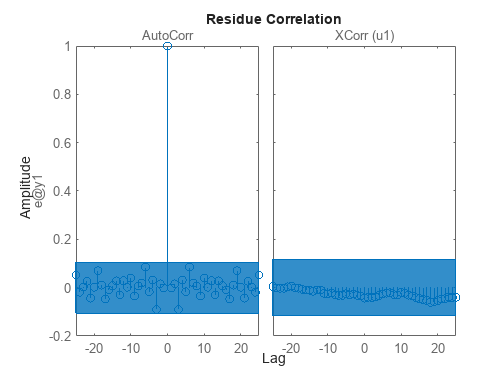

% Residual Correlation check
resid(Hv_Data,sysH)

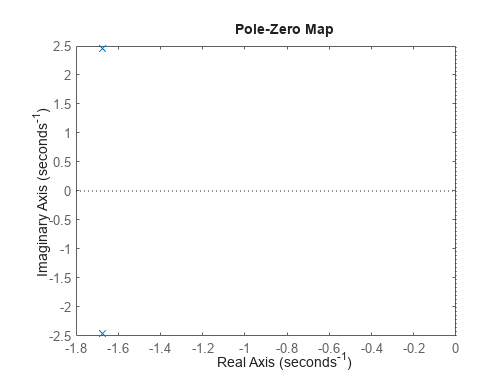

pzmap(sysH1)

dcgain(sysH1)

ans = 1.0145

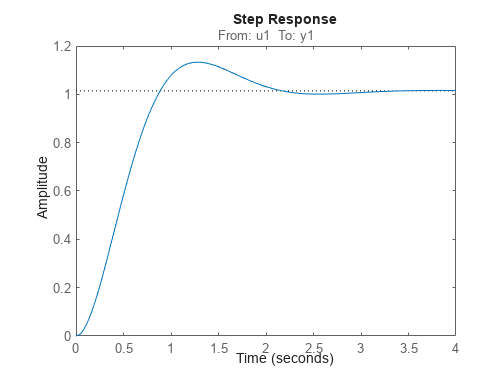

stepplot(sysH1)

stepinfo(sysH1)

ans = struct with fields:
         RiseTime: 0.5968
    TransientTime: 1.9760
     SettlingTime: 1.9760
      SettlingMin: 0.9198
      SettlingMax: 1.1330
        Overshoot: 11.6767
       Undershoot: 0
             Peak: 1.1330
         PeakTime: 1.2921


[y, t] = step(sysH1); % 'sysH1' is your system transfer function

% Steady-State Value
Hsteady_state = y(end)

Hsteady_state = 1.0161

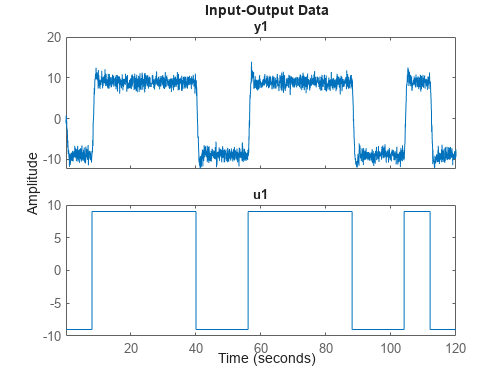

%%% Low SNR Noisy Data
% Run This Section
% PRBS inputs
samplepoint = 250;
switchconstant = 200;
amplitude = 9;
noise = 1;

% Load Data
Langle = out.Langle;
Lvoltage = out.Lvoltage;

% Create Identification and Validation Data Objects
LowData = iddata(Langle, Lvoltage, Ts);
plot(LowData)

Li_Data = LowData(1:1800);
Lv_Data = LowData(1801:2401);

Ldelay = delayest(LowData)

Ldelay = 6

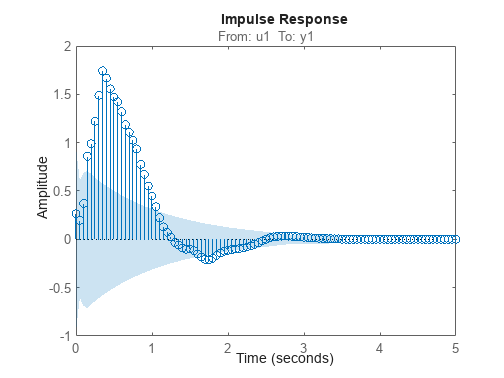

ImpRes = impulseest(LowData);
ImpRes_Plot = impulseplot(ImpRes);
showConfidence(ImpRes_Plot, 5)

n4sid(Li_Data, 1:10, "InputDelay", Ldelay);

MathWorks::System::IUserException in WebControllerFactory::create(): [Unrecognized method, property, or field 'ViewModel' for class 'handle'.

Error in matlab.ui.internal.componentframework.WebComponentController/getParentView (line 476)
            parentView = parentController.ViewModel;

Error in 


sysL = tfest(Li_Data, 2, 1, 0);
sysL1 = tfest(Li_Data, 2, 0, 0);

present(sysL)

                                                                                                                                                                                                                                                                                               
sysLL =                                                                                                                                                                                                                                                                                        
                                                                                                                                                                                                                                                                                               
  From input "u1" to output "y1":                                                                                                       

present(sysL1)

                                                                                                                                                                                                                                                                                                    
sysL1L1 =                                                                                                                                                                                                                                                                                           
                                                                                                                                                                                                                                                                                                    
  From input "u1" to output "y1":                                                                                        

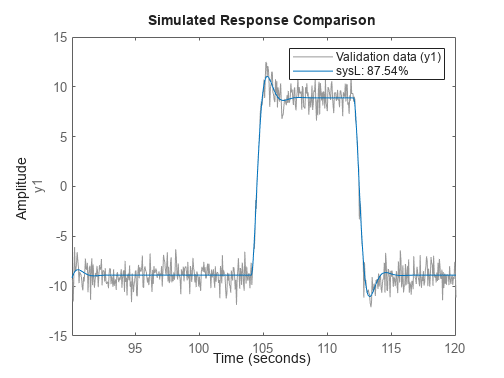


compare(Lv_Data,sysL)

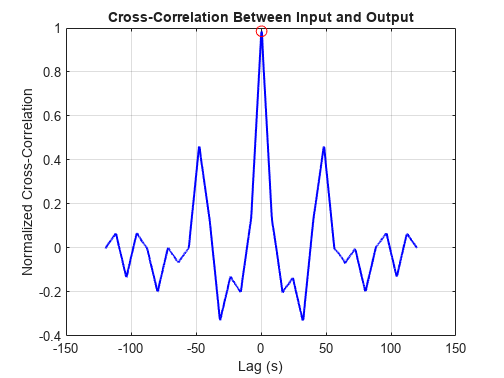


% Cross-Correlation to Check for Delay
[Lcorrelation, Llags] = xcorr(Langle, Lvoltage, 'normalized'); % Cross-correlation
[Lmax_corr, Lmax_idx] = max(Lcorrelation); % Find the maximum correlation
% Plot Cross-Correlation
figure;
plot(Llags * Ts, Lcorrelation, 'b', 'LineWidth', 1.5);
hold on;
plot(Llags(Lmax_idx) * Ts, Lmax_corr, 'ro', 'MarkerSize', 8); % Highlight max correlation point
xlabel('Lag (s)');
ylabel('Normalized Cross-Correlation');
title('Cross-Correlation Between Input and Output');
grid on;
hold off;

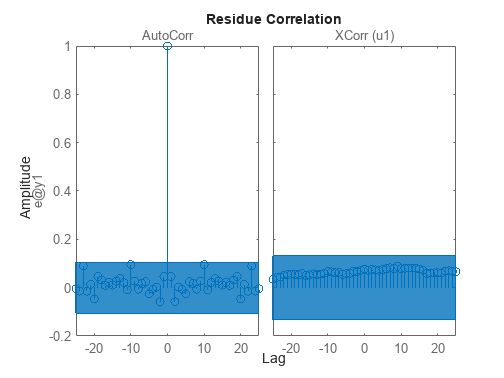

resid(Lv_Data,sysL)

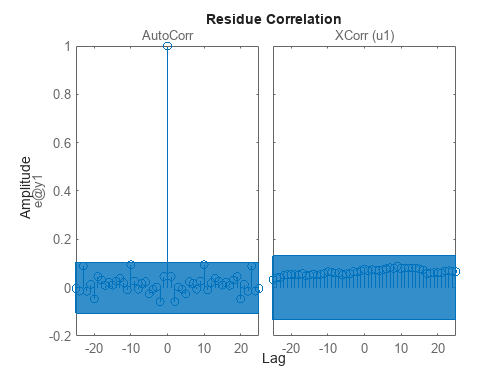

resid(Lv_Data,sysL1)

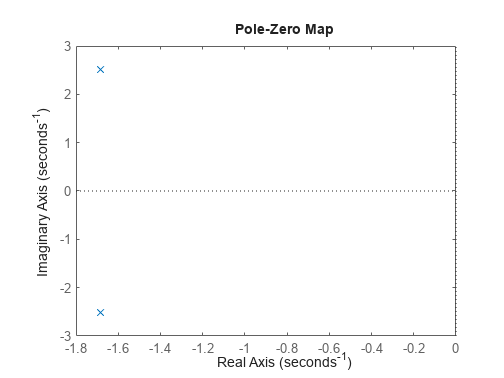

pzmap(sysL1)

dcgain(sysL1)

ans = 0.9885

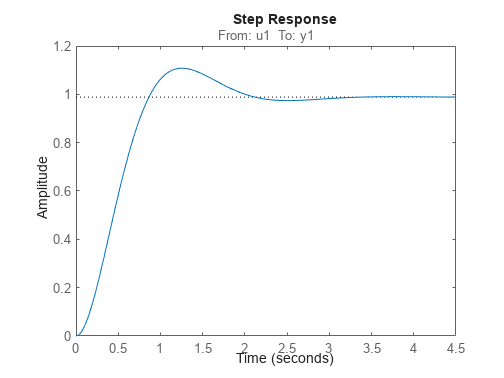

stepplot(sysL1)

stepinfo(sysL1)

ans = struct with fields:
         RiseTime: 0.5825
    TransientTime: 1.9387
     SettlingTime: 1.9387
      SettlingMin: 0.9090
      SettlingMax: 1.1081
        Overshoot: 12.0947
       Undershoot: 0
             Peak: 1.1081
         PeakTime: 1.2580


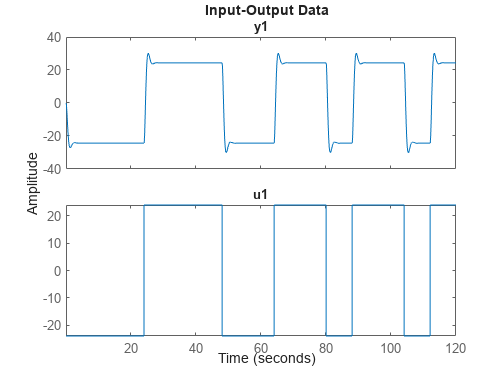

%%% Noisy Free Data
% Run This Section
% PRBS inputs
samplepoint = 250;
switchconstant = 200;
amplitude = 24;
noise = 0;

% Load Data
Nangle = out.Nangle;
Nvoltage = out.Nvoltage;

% Create Identification and Validation Data Objects
Ndata = iddata(Nangle, Nvoltage, Ts);
plot(Ndata)

i_Data = Ndata(1:1800); v_Data = Ndata(1801:2401);

Ndelay = delayest(Ndata)

Ndelay = 1

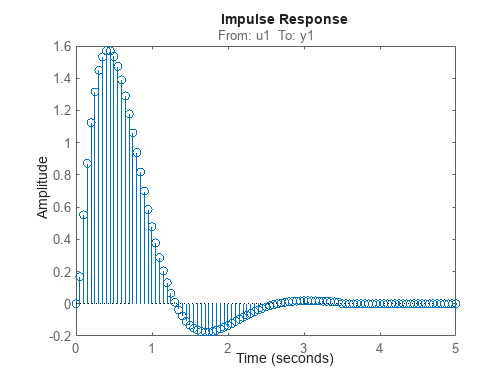

ImpRes = impulseest(Ndata);
ImpRes_Plot = impulseplot(ImpRes);
showConfidence(ImpRes_Plot, 5)

n4sid(i_Data, 1:10, "InputDelay", Ndelay);

sys  = tfest(i_Data, 4,0,0);
sys1 = tfest(i_Data, 4,1,0);
sys2 = tfest(i_Data, 4,2,0);
sys3 = tfest(i_Data, 4,3,0);

sysNF = tfest(i_Data,2,0,0);
sys1NF = tfest(i_Data,2,1,0);

present(sys)

                                                                                                                                                                                                                                                                                          
sys =                                                                                                                                                                                                                                                                                     
                                                                                                                                                                                                                                                                                          
  From input "u1" to output "y1":                                                                                                                      

present(sys1)

                                                                                                                                                                                                                                                                                               
sys11 =                                                                                                                                                                                                                                                                                        
                                                                                                                                                                                                                                                                                               
  From input "u1" to output "y1":                                                                                                       

present(sys2)

                                                                                                                                                                                                                                                                                               
sys22 =                                                                                                                                                                                                                                                                                        
                                                                                                                                                                                                                                                                                               
  From input "u1" to output "y1":                                                                                                       

present(sys3)

                                                                                                                                                                                                                                                                                               
sys33 =                                                                                                                                                                                                                                                                                        
                                                                                                                                                                                                                                                                                               
  From input "u1" to output "y1":                                                                                                       

present(sysNF)

                                                                                                                                                                                                                                                                                                    
sysNFNF =                                                                                                                                                                                                                                                                                           
                                                                                                                                                                                                                                                                                                    
  From input "u1" to output "y1":                                                                                        

present(sys1NF)

                                                                                                                                                                                                                                                                                                         
sys1NF1NF =                                                                                                                                                                                                                                                                                              
                                                                                                                                                                                                                                                                                                         
  From input "u1" to output "y1":                                                                         

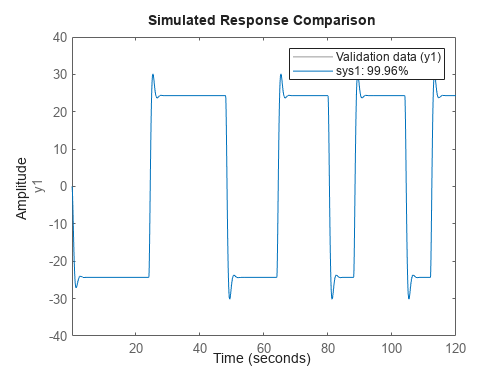

compare(Ndata,sys1)

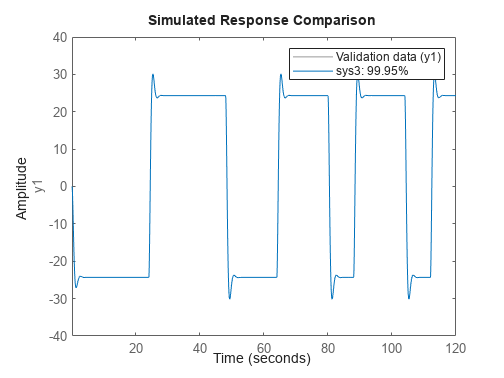

compare(Ndata,sys3)

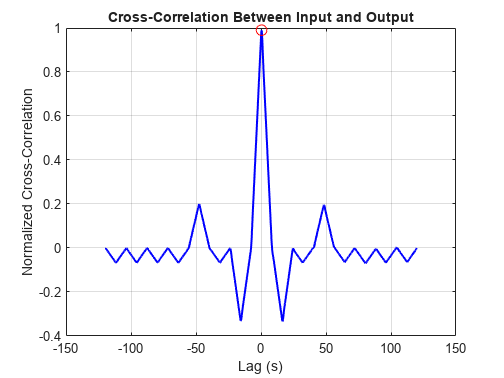

% Cross-Correlation to Check for Delay
[Ncorrelation, Nlags] = xcorr(Nangle, Nvoltage, 'normalized'); % Cross-correlation
[Nmax_corr, Nmax_idx] = max(Ncorrelation); % Find the maximum correlation
% Plot Cross-Correlation
figure;
plot(Nlags * Ts, Ncorrelation, 'b', 'LineWidth', 1.5);
hold on;
plot(Nlags(Nmax_idx) * Ts, Nmax_corr, 'ro', 'MarkerSize', 8); % Highlight max correlation point
xlabel('Lag (s)');
ylabel('Normalized Cross-Correlation');
title('Cross-Correlation Between Input and Output');
grid on;
hold off;

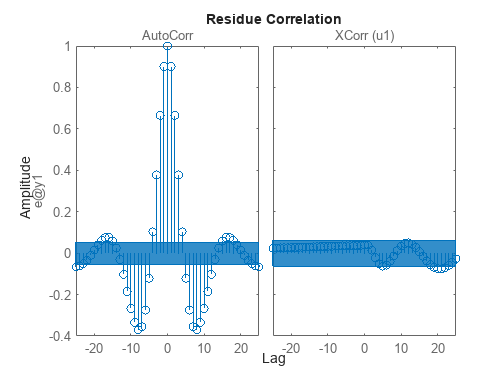

resid(Ndata,sys1)

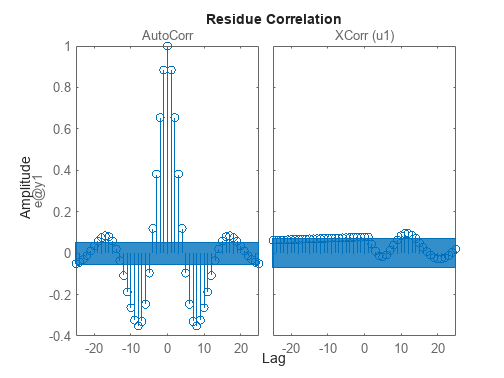

resid(Ndata,sys3)

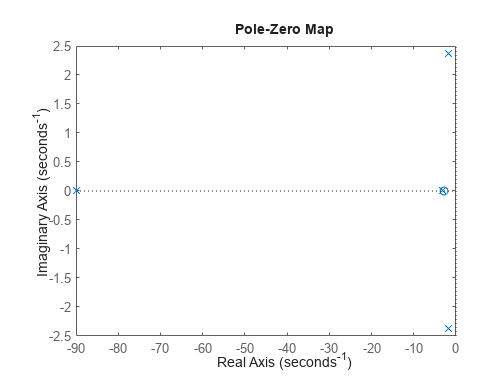

pzmap(sys1)

dcgain(sys1)

ans = 1.0130

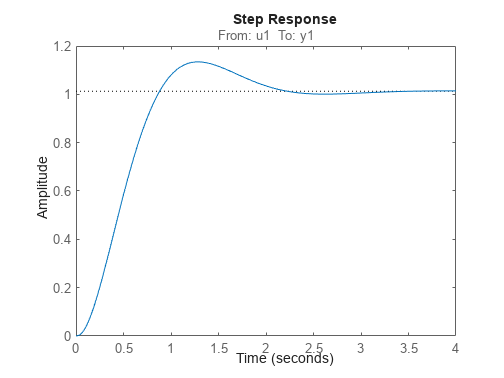

stepplot(sys1)

stepinfo(sys1)

ans = struct with fields:
         RiseTime: 0.5878
    TransientTime: 2.0132
     SettlingTime: 2.0132
      SettlingMin: 0.9309
      SettlingMax: 1.1344
        Overshoot: 11.9833
       Undershoot: 0
             Peak: 1.1344
         PeakTime: 1.2889


[y, t] = step(sys1); % 'sys1' is your system transfer function

% Steady-State Value
steady_state = y(end)

steady_state = 1.0142